Variational Gaussian Process

takes a mean function a kernel object and a list of inducing points

Training uses a mini-batch stochastic optimization.

clear all
%close all
clc

f1 = @(x) (6*x(:,1)-2).^2.*sin(12*x(:,2)-4);

xx = lhsdesign(200,2);
yy = f1(xx);

x1 = lhsdesign(1000,2);
y1 = f1(x1);
y1 = y1 + normrnd(0,0*y1 + 0.8);

ma = means.const(2)+means.linear([6 6])

ma =   const with properties:

         meanz: {[1×1 means.const]  [1×1 means.linear]}
        coeffs: {[2]  [6 6]}
    operations: {'+'}


a = kernels.Matern52(1,[0.2 0.5]);

a.signn = 0.5;

Z = VGP(ma,a,lhsdesign(20,2));

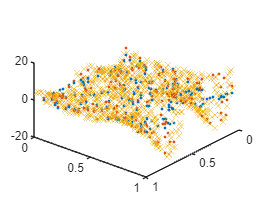

Z1 = Z.condition(x1,y1);

[ys,sig] = Z1.eval(xx);

figure
hold on
plot3(xx(:,1),xx(:,2),ys,'.')
plot3(xx(:,1),xx(:,2),yy,'.')
plot3(x1(:,1),x1(:,2),y1,'x')
view(-40,-40)

tic
[Z2,LL] = Z1.train(1);
toc

Elapsed time is 1.953651 seconds.


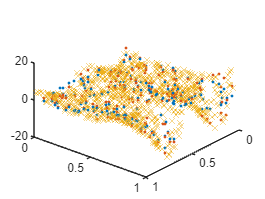

[ys,sig] = Z2.eval(xx);

figure
hold on
plot3(xx(:,1),xx(:,2),ys,'.')
plot3(xx(:,1),xx(:,2),yy,'.')
plot3(x1(:,1),x1(:,2),y1,'x')
view(-40,-40)


for i = 1:5
    xn = bads(@(x) Z2.newXuDiff(x),rand([1 2]),[0 0],[1 1]);
    Z2 = Z2.addInducingPoints(xn);
end

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        -2.00674               1                              Uncertainty test
     0           4        -2.00674               1            Initial mesh      
     1           6        -2.00674             0.5             Refine grid      Train
     2           9        -5.81714             0.5    Successful search (ES-wcm)      
     2          17        -5.81714            0.25             Refine grid      Train
     3          24        -5.92597           0.125             Refine grid      
     4          28        -6.00853           0.125    Successful search (ES-wcm)      
     4          29        -6.06462           0.125    Successful search (ES-wcm)      
     4          30        -6.12434           0.125    Successful search (ES-wcm)      
     4          31        -6.14613           0.125    Incremental search (ES

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        -1.70021               1                              Uncertainty test
     0           4        -1.70021               1            Initial mesh      
     1           6         -5.5426               1         Successful poll      Train
     2           9        -7.33241               1    Successful search (ES-wcm)      
     2          10        -7.44283               1    Incremental search (ES-wcm)      
     2          11        -7.46669               1    Incremental search (ES-ell)      
     2          12        -7.47866               1    Incremental search (ES-wcm)      
     2          13        -7.48465               1    Incremental search (ES-wcm)      
     2          14        -7.50265               1    Incremental search (ES-ell)      
     2          16        -7.50265             0.5             R

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2     -0.00602195               1                              Uncertainty test
     0           4        -1.06185               1            Initial mesh      
     1           6        -1.17913             0.5             Refine grid      Train
     2          13        -1.36378            0.25             Refine grid      
     3          14        -2.08078            0.25    Successful search (ES-wcm)      
     3          18        -2.10078            0.25    Incremental search (ES-wcm)      
     3          19        -2.11221            0.25    Incremental search (ES-ell)      
     3          20         -2.1124            0.25    Incremental search (ES-wcm)      
     3          21        -2.11254            0.25    Incremental search (ES-wcm)      
     3          24        -2.11254           0.125             Refine g

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2       -0.506359               1                              Uncertainty test
     0           4        -1.41688               1            Initial mesh      
     1           6        -1.41688             0.5             Refine grid      Train
     2           7        -5.26699             0.5    Successful search (ES-wcm)      
     2          16        -5.26699            0.25             Refine grid      Train
     3          19        -5.30209            0.25    Incremental search (ES-ell)      
     3          22        -5.30209           0.125             Refine grid      
     4          29        -5.30209          0.0625             Refine grid      
     5          30        -5.33708          0.0625    Successful search (ES-ell)      
     5          32        -5.34459          0.0625    Incremental search (ES-ell)

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        -1.13082               1                              Uncertainty test
     0           4        -1.13082               1            Initial mesh      
     1           6        -1.13082             0.5             Refine grid      Train
     2           7        -1.23168             0.5    Incremental search (ES-wcm)      
     2           9         -1.6645             0.5    Successful search (ES-wcm)      
     2          11        -1.76914             0.5    Incremental search (ES-ell)      
     2          13        -1.76968             0.5    Incremental search (ES-wcm)      
     2          16        -1.76968            0.25             Refine grid      Train
     3          17        -1.89015            0.25    Incremental search (ES-wcm)      
     3          19        -1.99997            0.25    Incremental 

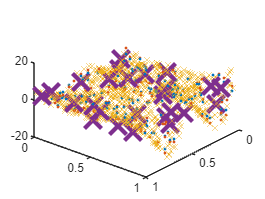


[ys,sig] = Z2.eval(xx);

figure
hold on
plot3(xx(:,1),xx(:,2),ys,'.')
plot3(xx(:,1),xx(:,2),yy,'.')
plot3(x1(:,1),x1(:,2),y1,'x')
plot3(Z2.Xu(:,1),Z2.Xu(:,2),0*Z2.Xu(:,1),'x','MarkerSize',18,'LineWidth',3)
view(-40,-40)

tic
[Z3,LL] = Z2.train(1);
toc

Elapsed time is 1.947933 seconds.


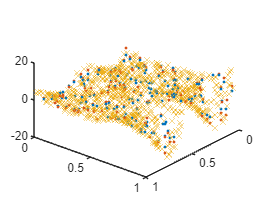


[ys,sig] = Z3.eval(xx);

figure
hold on
plot3(xx(:,1),xx(:,2),ys,'.')
plot3(xx(:,1),xx(:,2),yy,'.')
plot3(x1(:,1),x1(:,2),y1,'x')
view(-40,-40)